# [Automation with LSTM Network](https://apmonitor.com/pds/index.php/Main/LSTMAutomation)

The purpose of this exercise is to automate a temperature control process with an LSTM network. The LSTM network is trained from a PID (Proportional Integral Derivative) controller or a Model Predictive Controller (MPC). LSTM (Long Short Term Memory) networks are a special type of RNN (Recurrent Neural Network) that is structured to remember and predict based on long-term dependencies that are trained with time-series data. An LSTM repeating module has four interacting components.

The LSTM is trained (parameters adjusted) with an input window of prior data and minimized difference between the predicted and next measured value. Sequential methods predict just one next value based on the window of prior data. In this case, the error between the set point and measured value is the feature and the heater value is the output label.

**Background**: Proportional Integral Derivative (PID) control automatically adjusts a control output based on the difference between a set point (*SP*) and a measured process variable (*PV*). The value of the controller output u(t) is transferred as the system input.


$$e\left(t\right)=\textrm{SP}-\textrm{PV}$$



$$u\left(t\right)=u_{\textrm{bias}} +K_c \;e\left(t\right)+\frac{K_c }{\tau_I }\int_0^t e\left(t\right)\;\textrm{dt}-K_c {\;\tau }_D \frac{d\left(\textrm{PV}\right)}{\textrm{dt}}$$


The $u_{\textrm{bias}}$ term is a constant that is typically set to the value of $u\left(t\right)$ when the controller is first switched from manual to automatic mode. The three tuning values for a PID controller are the controller gain, $K_c$, the integral time constant $\tau_I$, and the derivative time constant $\tau_D$. The value of $K_c$ is a multiplier on the proportional error and integral term and a higher value makes the controller more aggressive at responding to errors away from the set point. The integral time constant $\tau_I$ (also known as integral reset time) must be positive and has units of time. As $\tau_I$ gets smaller, the integral term is larger because $\tau_I$ is in the denominator. Derivative time constant $\tau_D$ also has units of time and must be positive. The set point (*SP*) is the target value and process variable (*PV*) is the measured value that may deviate from the desired value. The error from the set point is the difference between the *SP* and *PV* and is defined as $e\left(t\right)=\textrm{SP}-\textrm{PV}$.

**Objective:** Train and deploy an LSTM network to adjust the heater (*Q*) to regulate the [**TCLab**](https://apmonitor.com/heat.htm) temperature to a requested set point. Submit source code and a summary memo (max 2 pages) of your results.

**You will need a TCLab apparatus to run all sections of this script.**

## Emulating a controller with an LSTM Network

The purpose of this exercise is to automate a temperature control process with an LSTM network. The LSTM network is trained from a PID (Proportional Integral Derivative) controller or a Model Predictive Controller (MPC). LSTM (Long Short Term Memory) networks are a special type of RNN (Recurrent Neural Network) that is structured to remember and predict based on long-term dependencies that are trained with time-series data. An LSTM repeating module has four interacting components.

The LSTM is trained (parameters adjusted) with an input window of prior data and minimized difference between the predicted and next measured value. Sequential methods predict just one next value based on the window of prior data. In this case, the error between the set point and measured value is the feature and the heater value is the output label.

**Program PID controller**

Apply this emulated control on the physical TCLab controller. Use the emulator for training. Create the PID function below.

### **Generate data for training LSTM**

There are two options to complete this task. You can run your own TCLab device for 90 minutes with the code below under MATLAB TCLab Code or you can run the Python TCLab Simulation Code to run a digital twin of the TCLab via a Python script. Both methods will create a csv that can be used in the following sections of the Case Study.

#### **MATLAB TCLab Code**

If you have troubles running this code, please view [Dr. Hedengren's Process Controls Course](https://apmonitor.com/pdc/index.php/Main/ArduinoSetup) for details to set up MATLAB with the TCLab.

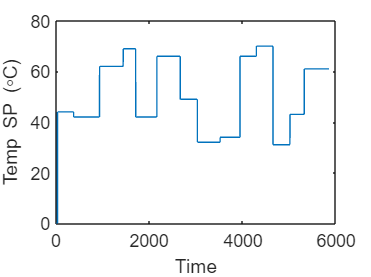

% Set up run parameters
% Run time in minutes
run_time = 90.0;

% Number of cycles
loops = int32(60.0 * run_time);

% Arrays for storing data
T1 = zeros(loops, 1); % measured T (degC)
Q1 = zeros(loops, 1); % Heater values
tm = zeros(loops, 1); % Time

% Temperature set point (degC)
Tsp1 = zeros(loops, 1);

% Vary temperature set point
end_idx = 30; % leave 1st 30 seconds of temp set point as room temp
while end_idx <= loops
    start_idx = end_idx;
    % Keep new temp set point value for anywhere from 4 to 10 min
    end_idx = end_idx + randi([240, 600]);
    Tsp1(start_idx:end_idx) = randi([30, 70]);
end

% Plot
plot(Tsp1);
xlabel('Time', 'FontSize', 14);
ylabel('Temp SP (\circC)', 'FontSize', 14);
set(gca, 'FontSize', 12);

**Data Collection**

Change the COM Port to match your computer and click the runTCLab button below to run the code. By default, all TCLab and Python code is turned off. Please, click through each sections of code that you would like to run depending on the code that you would like to run. For all runTCLab sections, you will need a TCLab apparatus.

runTCLab = false;

if runTCLab
    % Data collection
    lab = tclab("COM4"); % Change COM Port number to match your computer
    
    % Find current T1, T2
    disp(['Temperature 1: ' num2str(lab.T1, '%0.2f') ' °C']);
    disp(['Temperature 2: ' num2str(lab.T2, '%0.2f') ' °C']);
    
    % Integral error
    ierr = 0.01;
    % Integral absolute error
    iae = 0.0;
    
    prev_time = 0;
    for i = 1:(loops-1)
        t = i;
        tm(i) = t;
        dt = t - prev_time;
    
        % Read temperatures in Kelvin
        T1(i) = lab.T1;
    
        % Integral absolute error
        iae = iae + abs(Tsp1(i) - T1(i));
    
        % Calculate PID output
        [Q1(i), P, ierr, D] = pid(Tsp1(i), T1(i), T1(i), ierr, dt);
    
        % Write heater output (0-100)
        lab.Q1(Q1(i));
    
        
        % Print line of data
        if i == 1;
            disp(['  tm '     '  Tsp1 '    '  T1 '    '   Q1 ' ...
                 '   P '      '   ierr '     '   D ' ...
                     '   iae ' ])
        end
        
        % Print current values of the TCLab apparatus
        if mod(i, 100) == 0
            disp([' ' num2str(tm(i), '%6.1f') ' ' num2str(Tsp1(i), '%6.2f') ' ' num2str(T1(i), '%6.2f') ' ' ...
                num2str(Q1(i), '%6.2f') ' ' num2str(P, '%6.2f') ' ' num2str(ierr, '%6.2f') ' ' ...
                num2str(D, '%6.2f') ' ' num2str(iae, '%6.2f')]);
        end
        prev_time = t;
    end
    
    % Close the connection to the TCLab
    clear lab;
    
    % Save the data as a CSV
    Q1 = Q1(1:i);
    T1 = T1(1:i);
    Tsp = Tsp1(1:i);
    
    data = table(Q1, T1, Tsp);
    writetable(data, 'PID_train_data.csv');
    
    % Plot data
    figure;
    plot(data.Q1, 'b-', 'LineWidth', 1, 'DisplayName', 'Q1 (%)');
    hold on;
    plot(data.T1, 'r-', 'LineWidth', 1, 'DisplayName', 'T1 (^oC)');
    plot(data.Tsp, 'k-', 'LineWidth', 1, 'DisplayName', 'SP (^oC)');
    legend('Location', 'best');
    xlabel('Time');
    ylabel('Value');
    title('PID Training');
    grid on;
    hold off;
end

#### Python TCLab Simulation Code

As stated above, this is the second method to gain TCLab data using the Python Digital Twin. The code will run the same code as the MATLAB code above but using Python syntax. The Python version runs a Digital Twin to increase the speed and to give data faster. To run Python code in MATLAB, please ensure that your MATLAB program was opened through the Anaconda Prompt window.

To run code below, open the Anaconda Prompt Window. Type MATLAB in the command line and press enter. MATLAB will now open under the dependency of Anaconda. Next change your directory to be the location of the Python file below. Click the check box below. Run the code.

doPythonFile = false;

if doPythonFile
    % Collect Data
    pyrunfile('TCLab_Simulation.py')
    
    % Read data from CSV file
    data = readtable('PID_train_data.csv');
    
    % Plot data
    figure;
    plot(data.Q1, 'b-', 'LineWidth', 1, 'DisplayName', 'Q1 (%)');
    hold on;
    plot(data.T1, 'r-', 'LineWidth', 1, 'DisplayName', 'T1 (^oC)');
    plot(data.Tsp, 'k-', 'LineWidth', 1, 'DisplayName', 'SP (^oC)');
    legend('Location', 'best');
    xlabel('Time');
    ylabel('Value');
    title('PID Training');
    grid on;
    hold off;
end

### Format Data for LSTM

Feature engineering: create SP error feature and analyze feature importance. For information on the fsrmrmr function click on the [link](https://www.mathworks.com/help/stats/fsrmrmr.html).

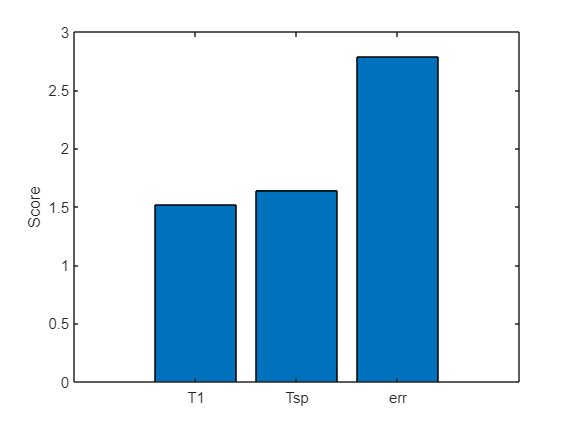

% Create new feature: setpoint error
data.err = data.Tsp - data.T1;

% Load possible features
X = data(:, {'T1', 'Tsp', 'err'});
y = data.Q1;

% SelectKBest feature selection
[~,scores] = fsrmrmr(table2array(X), y);

% Plot features
figure;
bar(scores);
xticklabels(X.Properties.VariableNames);
ylabel('Score');

Feature selection, scaling, and formatting data to LSTM input format

X = data(:, {'Tsp', 'err'});
y = data.Q1;

% Scale X data
mu = table2array(mean(X,1));
sigma = table2array(std(X,0,1));
Xs = table2array((X-mu)./sigma);

% Scale y data
muy = mean(y,1);
sigmay = std(y,0,1);
ys = (y-muy)./sigmay;

% Each input uses last 'window' number of Tsp and err to predict the next Q1
window = 15;
X_lstm = zeros(size(Xs,1),window,2);
y_lstm = zeros(size(ys,1),1);
for i = window:size(data,1)
    X_lstm(i-window+1,:,:) = Xs(i-window+1:i, :);
    y_lstm(i-window+1) = ys(i);
end

% Reshape data to format accepted by LSTM
X_lstm = permute(X_lstm, [3,2,1]);

% Split into train and test
[trainIdx,~, testIdx] = dividerand(size(y_lstm,1),0.8,0,0.2);
Xtrain = X_lstm(:, :, trainIdx);
Xtest = X_lstm(:, :, testIdx);
ytrain = y_lstm(trainIdx);
ytest = y_lstm(testIdx);

### **Create/Train LSTM**

Quick Reminder: You can build the LSTM network using the Deep Network Designer App. Feel free to try it out and replace the code below with your own network!

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |         1.03 |          0.5 |          0.0100 |
|      20 |          20 |       00:00:24 |         0.25 |      3.1e-02 |          0.0100 |
|========================================================================================|
Training finished: Max epochs completed.


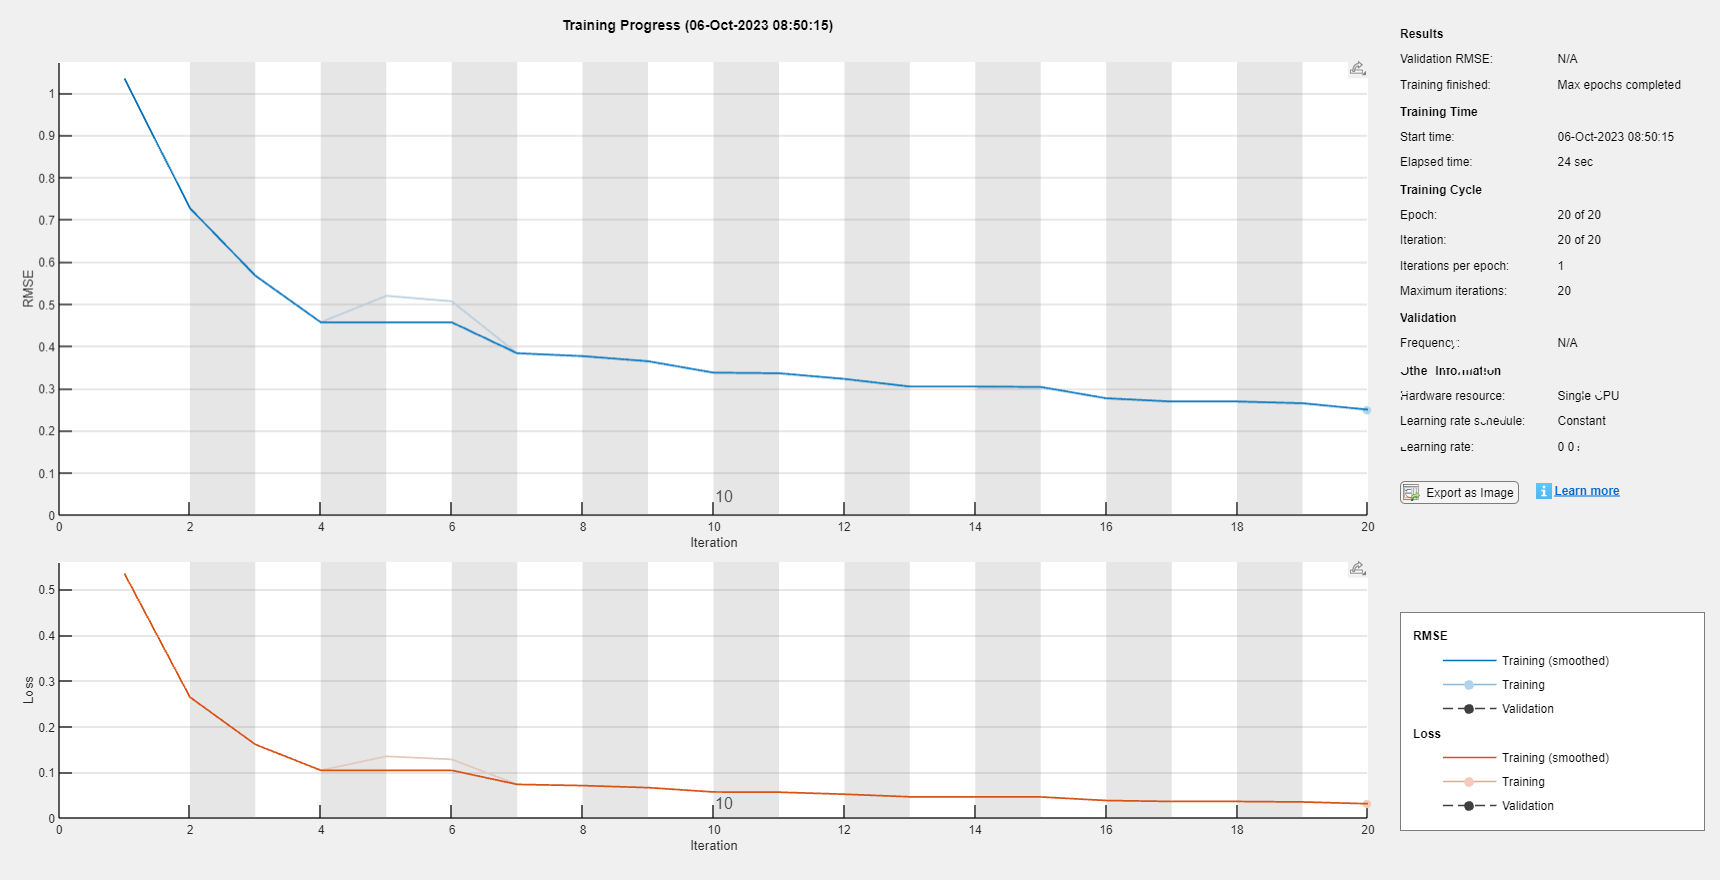

% Set up layers for the LSTM
layers = [ sequenceInputLayer([15,2]) % ,'NormalizationDimension','auto'
    flattenLayer()
    lstmLayer(50)
    dropoutLayer(0.2)
    lstmLayer(50,'OutputMode','sequence')
    dropoutLayer(0.2)
    lstmLayer(20,'OutputMode','sequence')
    fullyConnectedLayer(1)
    regressionLayer
    ];

% Clarify more options for the fit
options = trainingOptions('adam', ...
    MaxEpochs=20, ...
    MiniBatchSize=250, ...
    Verbose=true, ...
    ValidationPatience=10, ...
    InitialLearnRate=0.01,...
    Plots='training-progress');

% Train network
[lstm,info] = trainNetwork(pagetranspose(Xtrain),ytrain',layers,options); 

**Preliminary model performance assessment**

**Assess the model using previous data.**

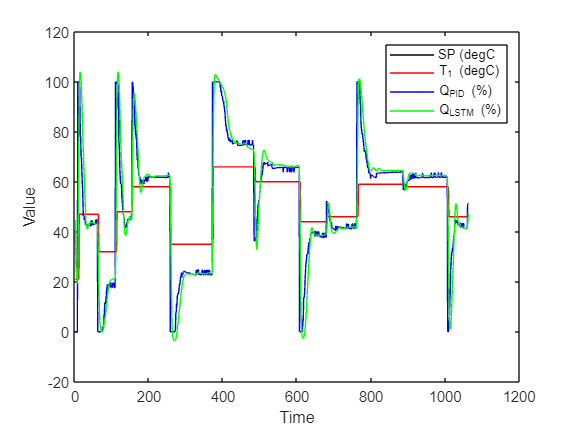

yp_s = predict(lstm, pagetranspose(Xtest));

% Unscale data
Xtest_us = permute(Xtest,[2,1,3]) .* sigma + mu;
ytest_us = ytest * sigmay + muy;
yp = yp_s * sigmay + muy;

% Derive Tsp (sp) and T1 (pv) from X data
sp = permute(Xtest_us(1,1,:),[3,2,1]);
% pv = permute(Xtest_us(1,1,:) + Xtest_us(2,1,:),[3,2,1]);
pv = permute(Xtest_us(2,1,:),[3,2,1]);

% Plot SP, PID response, and LSTM response
plot(sp, 'k-','DisplayName','SP (degC');
hold on;
plot(pv, 'r-','DisplayName','T_1 (degC)');
plot(ytest_us, 'b-','DisplayName','Q_{PID} (%)');
plot(yp, 'g-','DisplayName','Q_{LSTM} (%)');
legend();
xlabel('Time');
ylabel('Value');
hold off;

**Generate Set Point (SP) data for test**

% Run time in minutes
run_time = 45.0; %45.0

% Number of cycles
loops = fix(60.0 * run_time);

% Temperature set point (degC)
Tsp = ones(loops, 1);
T1 = Tsp;

% Vary temperature setpoint
endIndex = window + 15; % Leave 1st window + 15 seconds of temp set point as room temp
while endIndex <= loops
    startIndex = endIndex;
    % Keep new temp set point value for anywhere from 4 to 10 min
    endIndex = endIndex + randi([240, 600]);
    Tsp(startIndex:endIndex) = randi([30, 69]);
end

if size(Tsp,1) > size(loops,1)
    Tsp = Tsp(1:loops);
end

% Leave last 120 seconds as room temp
Tsp(end-120:end) = Tsp(1);
plot(Tsp);
xlabel('Time');
ylabel('Temperature Set Point (°C)');

### **Run the controller with the LSTM**

runTCLab = false;

if runTCLab
    clear lab;
    % Data collection
    lab = tclab("COM4"); % Change COM Port number to match your computer
    
    % Run test
    % Find current T1, T2
    fprintf('Temperature 1: %.2f °C\n', lab.T1);
    fprintf('Temperature 2: %.2f °C\n', lab.T2);
    
    % Integral error
    ierr = 0.0;
    % Integral absolute error
    iae = 0.0;
    
    % Set up arrays to collect data
    Qpid = zeros(loops-1);
    Q1c_s = zeros(loops,1);
    
    % Assign starting position
    start_time = 0;
    prev_time = 0;
    Q1c = 0;
    for i = 2:(loops-1)
        t = i;
        dt = t - prev_time;
    
        % Read temperature (C)
        T1(i) = lab.T1;
    
        % Run LSTM model to get Q1 value for control
        if i >= window
            % Load data for model
            T1_m = T1(i-window+1:i);
            Tsp_m = Tsp(i-window+1:i);
    
            % Predict and store LSTM value for comparison
            % Calculate error (necessary feature for LSTM input)
            err = Tsp_m - T1_m;
        
            % Format data for LSTM input
            X = [Tsp_m, err];
            Xs = (X-mu)./sigma;
            Xs = permute(Xs, [2,1,3]);
            
            % Predict Q for controller and unscale
            Q1c_s(i) = predict(lstm, pagetranspose(Xs));
            Q1c = Q1c_s(i).*sigmay + muy;
            % Q1c = Q1c(1);
            
            % Ensure Q1c is between 0 and 100
            Q1c = max(0.0, min(Q1c, 100.0));
    
    
        end
        lab.Q1(Q1c);
        prev_time = t;
        pause(1);
    
    end
    
    clear lab;
    
    Q1cgraph = Q1c_s*sigmay + muy;
end


% Plot SP, T1, and LSTM responses
plot(Tsp, 'k-', 'DisplayName', 'SP (^oC)');
hold on;
plot(T1, 'r-', 'DisplayName', 'T_1 (^oC)');
plot(Q1cgraph, 'g-', 'DisplayName', 'Q_{LSTM} (%)');
% Add legend
legend('Location', 'northeast');
% Set y-axis limits
ylim([0, 100]);
% Set labels and tick sizes
xlabel('Time (s)', 'FontSize', 14);
ylabel('Value', 'FontSize', 14);
set(gca, 'FontSize', 12);
hold off;

As you can see, the LSTM performs well by learning from the PID data given to it. LSTM is a great method to control the TCLab process and many others.

#### Supporting Function

The following PID controller has been previously tuned to match the TCLab apparatus. You should not need to update the values below.

function [op,P,I,D,ierr] = pid(sp,pv,pv_last,ierr,dt) % PID
    % PID Parameters
    Kc = 6.0;
    tauI = 75.0; % sec
    tauD = 0.0;  % sec   
    
    % PID coefficients in terms of tuning parameters
    KP = Kc;
    KI = Kc / tauI;
    KD = Kc * tauD;
    
    % ubias for controller (initial heater)
    op0 = 0;
    
    % upper and lower bounds on heater level
    ophi = 100;
    oplo = 0;
    
    % calculate the error
    error = sp - pv;
    
    % calculate the integral error
    ierr = ierr + KI * error * dt;
    
    % calculate the measurement derivative
    if dt >= 1e-8
        dpv = (pv - pv_last) / dt;
    else
        dpv = 0.0;
    end
    
    % calculate the PID output
    P = KP * error;
    I = ierr;
    D = -KD * dpv;
    op = op0 + P + I + D;
    
    % implement anti-reset windup
    if op < oplo || op > ophi
        I = I - KI * error * dt;
        % clip output
        op = max(oplo, min(ophi, op));
    end
    
    % return the controller output and PID terms
end